# Problem 1

Student 1: Laura Train García

Student 2: Cristina Sánchez Martín

Data of the problem:

clear;clc; close all;

% general parameters
muE = 398600;                   % mu Earth [km^3/s^2]
Rearth = 6371;                  % mean radius of Earth [km]


## Lambert example

The following example tries to test the Lambert algorithm for the simplest case one can verify, a Hohmann transfer. The verification will consist of solving the problem using both methods separately and then asserting the result is the same. The transfer will take place at the following 

a = 30,000 km

e = 0

Ω = 210º

i = 25º

ω = 25º

Note that e = 0 because a Hohmann transfer implies two circular orbits.

Let us solve the Hohmann transfer first.

% data for the initial point
example.h1 = 2000;                           % altitude [km]
example.a1 = Rearth + example.h1;            % semi-major axis [km]
example.e1 = 0;                              % eccentricity
example.Omega1 = deg2rad(210);               % RAAN [rad]
example.inc1 = deg2rad(25);                  % inclination [rad]
example.omega1 = deg2rad(36);                % argument of the periapsis [rad]
example.theta1 = 0;                          % true anomaly [rad]

% data for the final point
example.a2 = 30000;                          % semi-major axis [km]
example.e2 = 0;                              % eccentricity
example.Omega2 = deg2rad(210);               % RAAN [rad]
example.inc2 = deg2rad(25);                  % inclination [rad]
example.omega2 = deg2rad(36);                % argument of the periapsis [rad]
example.theta2 = deg2rad(180);               % true anomaly [rad]


% compute initial position and initial orbit velocity from coe
[example.r1, example.v0] = coe2rv(muE, example.a1, example.e1,  example.Omega1, ...
                                  example.inc1, example.omega1, example.theta1);

% compute final position and final orbit velocity from coe
[example.r2, example.vF] = coe2rv(muE, example.a2, example.e2, example.Omega2, ...
                                  example.inc2, example.omega2, example.theta2);

% compute velocities using a Hohmann transfer
[example.HT.v1, example.HT.v2, example.HT.dV] = HT(muE, example.a1, example.a2);

fprintf("Hohmann transfer results \n")

Hohmann transfer results 


fprintf("The initial velocity of the transfer is %.3f m/s \n", example.HT.v1)

The initial velocity of the transfer is 8.629 m/s 


fprintf("The final velocity of the transfer is %.3f m/s \n", example.HT.v2)

The final velocity of the transfer is 2.408 m/s 


fprintf("The total deltaV is %.3f m/s \n\n", example.HT.dV)

The total deltaV is 2.966 m/s 



One of the inputs for the Lambert problem is the transfer time. Let's compute the transfer time for the Hohmann transfer.

% compute the transfer time
[example.tf, example.eHT, example.aHT] = transfer_time_HT(muE, ...
                                                          example.a1, example.a2);

% solve Lambert solution
example.lambert.k = cross(example.r1,example.v0)/norm(cross(example.r1,example.v0));
[example.lambert.v1, example.lambert.v2] = Lambert(example.r1, example.r2, ...
                                                   example.lambert.k, example.tf, ...
                                                   muE);

% deltaV of the first firing
example.lambert.dV1 = norm(example.lambert.v1-example.v0);

% deltaV of the second firing
example.lambert.dV2 = norm(example.vF-example.lambert.v2);

% total deltaV
example.lambert.dV = abs(example.lambert.dV1) + abs(example.lambert.dV2);

fprintf("Lambert analysis results \n")

Lambert analysis results 


fprintf("The initial velocity of the transfer is %.3f m/s \n", ...
norm(example.lambert.v1))

The initial velocity of the transfer is 8.629 m/s 


fprintf("The final velocity of the transfer is %.3f m/s \n", ...
norm(example.lambert.v2))

The final velocity of the transfer is 2.408 m/s 


fprintf("The total deltaV is %.3f m/s \n\n", example.lambert.dV)

The total deltaV is 2.966 m/s 



Therefore, both methods give the same result.

To enable the reader visualize the initial, final and transfer orbits, let us plot the results.

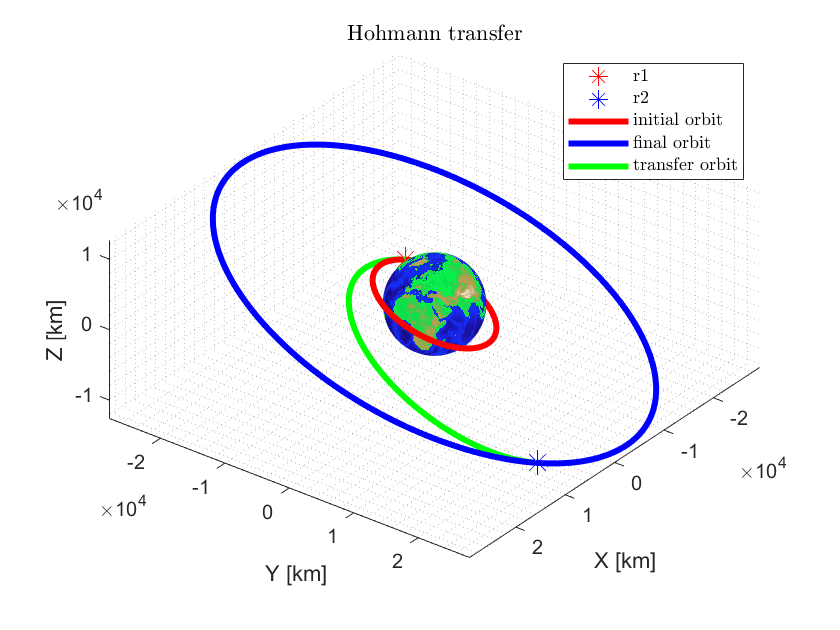

% get ellipse coordinates for initial, final and transfer orbits
example.r1_coords = ellipse_coords(muE, example.a1, example.e1, ...
                                   example.Omega1, example.inc1, example.omega1);
example.r2_coords = ellipse_coords(muE, example.a2, example.e2, ...
                                   example.Omega2, example.inc2, example.omega2);
example.rt_coords = ellipse_coords(muE, example.aHT, example.eHT, ...
                                   example.Omega1, example.inc1, example.omega1);

% plot initial, final and transfer orbits
figure(1)
earth_sphere('km')
hold on
plot3(example.r1(1), example.r1(2), example.r1(3), 'r*', ...
    example.r2(1), example.r2(2), example.r2(3), 'b*', 'MarkerSize',12)
hold on 
plot3(example.r1_coords(1,:), example.r1_coords(2,:), example.r1_coords(3,:), 'r', ...
      example.r2_coords(1,:), example.r2_coords(2,:), example.r2_coords(3,:), 'b', ...
      example.rt_coords(1,1:(end/2)), example.rt_coords(2,1:(end/2)), ...
      example.rt_coords(3,1:(end/2)), 'g', 'LineWidth',3)
title('Hohmann transfer','interpreter','latex');
hold off
grid minor
legend('r1','r2','initial orbit','final orbit','transfer orbit','location', ...
       'northeast','interpreter','latex');
axis equal

## Initial exploration

The initial exploration will consist of evaluating the cost function in a 3D grid of points. Note that an increase on the number of points will mean a significant increase in the computational time but also on the accuracy of the results. Since later on, an optimizer will be used in order to find the minimum deltaV accounting for the three variables, let's use only 20 points for the initial exploration.

% orbital period of the final orbit
exploration.tau = orbital_period(example.a2, muE);

% number of points for the exploration
N = 20;

% vector of theta1, theta2, and transfer time
exploration.theta1 = linspace(0,2*pi,N);
exploration.theta2 = linspace(0,2*pi,N);
exploration.tf = linspace(0,exploration.tau,N);

% get a grid with all the points to evaluate
[exploration.thth1,exploration.thth2,exploration.tftf] = meshgrid(exploration.theta1, ...
                                                                  exploration.theta2, ...
                                                                  exploration.tf);
% preallocate DV
exploration.DV = zeros(N,N,N);

% evaluate cost function for each point in the grid
for i = 1:N
    for j = 1:N
        for k = 1:N
            exploration.DV(i,j,k) = cost(exploration.thth1(i,j,k), exploration.thth2(i,j,k), ...
                exploration.tftf(i,j,k));
        end
    end
end

Let's plot some other isosurfaces for the some expensive transfers.

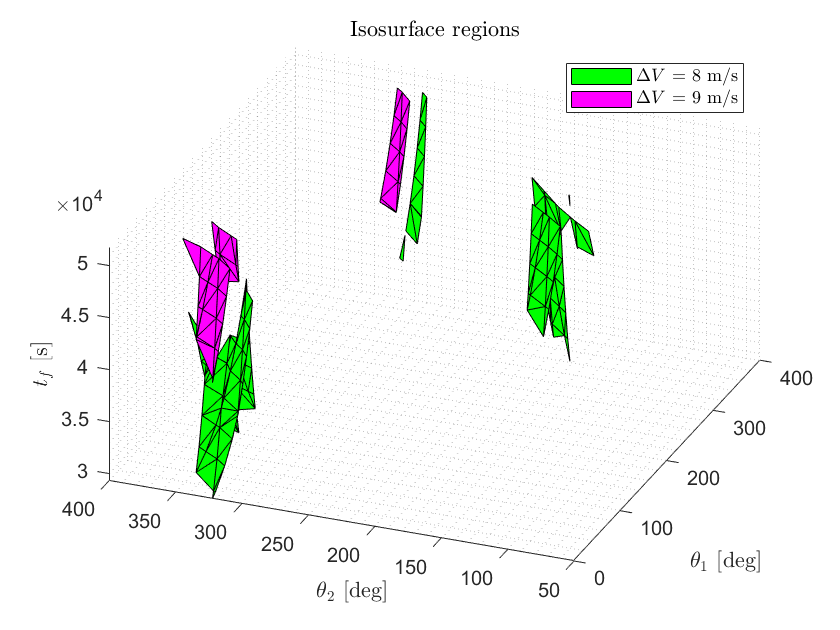

figure(4)

% isosurface for deltaV = 7 m/s
p = patch(isosurface(rad2deg(exploration.thth1),rad2deg(exploration.thth2), ...
                     exploration.tftf,exploration.DV,7));
p.FaceColor = 'green';
hold on

% isosurface for deltaV = 8 m/s
v = patch(isosurface(rad2deg(exploration.thth1),rad2deg(exploration.thth2), ...
                     exploration.tftf,exploration.DV,8));
v.FaceColor = 'magenta';
hold on

v = [-5 -2 5];
view(v);
xlabel('$\theta_1$ [deg]','interpreter','latex')
ylabel('$\theta_2$ [deg]','interpreter','latex')
zlabel('$t_f$ [s]','interpreter','latex')
legend('$\Delta V$ = 8 m/s','$\Delta V$ = 9 m/s','Location', ...
       'northeast','interpreter','latex');
title('Isosurface regions','interpreter','latex');
grid minor
hold off

Let's plot some isosurfaces por the cheapeast transfers.

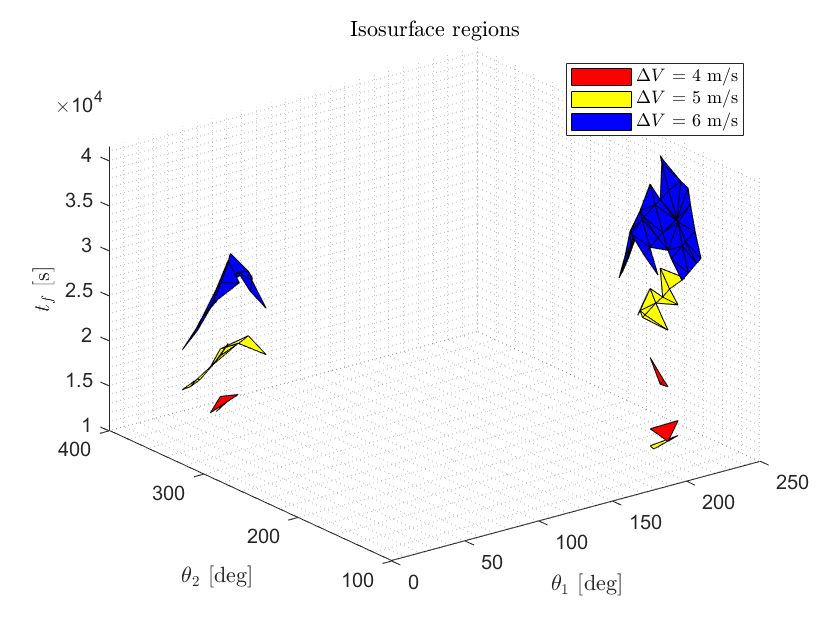

% plot isosurfaces
figure(5)

% isosurface for deltaV around 3 m/s
p = patch(isosurface(rad2deg(exploration.thth1),rad2deg(exploration.thth2), ...
                     exploration.tftf,exploration.DV,4));
p.FaceColor = 'red';
view(3); 
hold on

% isosurface for deltaV around 4 m/s
v = patch(isosurface(rad2deg(exploration.thth1),rad2deg(exploration.thth2), ...
                     exploration.tftf,exploration.DV,5));
v.FaceColor = 'yellow';
view(3); 
hold on

% isosurface for deltaV around 5 m/s
w = patch(isosurface(rad2deg(exploration.thth1),rad2deg(exploration.thth2), ...
                     exploration.tftf,exploration.DV,6));
w.FaceColor = 'blue';
view(3); 

xlabel('$\theta_1$ [deg]','interpreter','latex')
ylabel('$\theta_2$ [deg]','interpreter','latex')
zlabel('$t_f$ [s]','interpreter','latex')
legend('$\Delta V$ = 4 m/s','$\Delta V$ = 5 m/s', '$\Delta V$ = 6 m/s', ...
       'Location','northeast','interpreter','latex');
title('Isosurface regions','interpreter','latex');
grid minor
hold off

Let's fin the minimum value for deltaV on the grid and its corresponding theta1, theta2 and tf

% find the minimum dV in the grid
[exploration.min.dV,exploration.min.index] = min(exploration.DV(:));
[exploration.min.I1,exploration.min.I2,exploration.min.I3] = ind2sub(size(exploration.DV), ...
                                                                   exploration.min.index);

% find the theta1, theta2 and tf associated to minimum dV
exploration.min.theta1 = exploration.thth1(exploration.min.I1, exploration.min.I2, ...
                                           exploration.min.I3);       % true anomaly [rad]
exploration.min.theta2 = exploration.thth2(exploration.min.I1, exploration.min.I2, ...
                                           exploration.min.I3);       % true anomaly [rad]
exploration.min.tf = exploration.tftf(exploration.min.I1, exploration.min.I2, ...
                                           exploration.min.I3);

fprintf("The minimum deltaV point in the grid is %.3f km/s \n", exploration.min.dV)

The minimum deltaV point in the grid is 3.462 km/s 


fprintf("θ1 = %.3f deg, θ2 = %.3f deg and tf = %.3f s \n", ...
rad2deg(exploration.min.theta1), rad2deg(exploration.min.theta2), exploration.min.tf)

θ1 = 208.421 deg, θ2 = 151.579 deg and tf = 16330.172 s 


## Optimization of the transfer

Now, let's explore the minimum deltaV with the corresponding theta1, theta2 and tf values

% use fminsearch to find minimum cost
cost_function = @(x) cost(x(1), x(2), x(3));
x0 = [exploration.min.theta1, exploration.min.theta2, exploration.min.tf];
options = optimset('MaxFunEvals',1000);
opt_sol = fminsearch(cost_function,x0,options);

% get minimum theta1, theta2 and tf
optimum.theta1 = opt_sol(1);
optimum.theta2 = opt_sol(2);
optimum.tf = opt_sol(3);
fprintf("θ1 = %.3f deg, θ2 = %.3f deg and tf = %.3f s \n", ...
rad2deg(optimum.theta1), rad2deg(optimum.theta2), optimum.tf)

θ1 = 232.626 deg, θ2 = 168.697 deg and tf = 14987.226 s 


fprintf("The minimum deltaV of the transfer is %.3f km/s \n", cost_function(opt_sol))

The minimum deltaV of the transfer is 3.388 km/s 


The corresponding transfer orbit is computed by applying Lambert algorithm.

% data for the initial point
optimum.h1 = 2000;                                   % altitude [km]
optimum.a1 = Rearth + optimum.h1;                    % semi-major axis [km]
optimum.e1 = 0;                                      % eccentricity
optimum.Omega1 = 0;                                  % RAAN [rad]
optimum.inc1 = 0;                                    % inclination [rad]
optimum.omega1 = 0;                                  % argument of the periapsis [rad]

% data for the final point
optimum.a2 = 30000;                                  % semi-major axis [km]
optimum.e2 = 0.1;                                    % eccentricity
optimum.Omega2 = deg2rad(210);                       % RAAN [rad]
optimum.inc2 = deg2rad(25);                          % inclination [rad]
optimum.omega2 = deg2rad(36);                        % argument of the periapsis [rad]


% find intial and final positions
optimum.r1 = coe2rv(muE, optimum.a1, optimum.e1, optimum.Omega1, ...
                    optimum.inc1, optimum.omega1, optimum.theta1);
optimum.r2 = coe2rv(muE, optimum.a2, optimum.e2, optimum.Omega2, ...
                    optimum.inc2, optimum.omega2, optimum.theta2);

% solve long arc Lambert solution
optimum.k = -cross(optimum.r1,optimum.r2)/norm(cross(optimum.r1,optimum.r2));

% solve Lambert algorithm
[optimum.v1, optimum.v2] = Lambert(optimum.r1, optimum.r2, optimum.k, optimum.tf, muE);


To enable the reader visualize the orbits, let us plot the results.

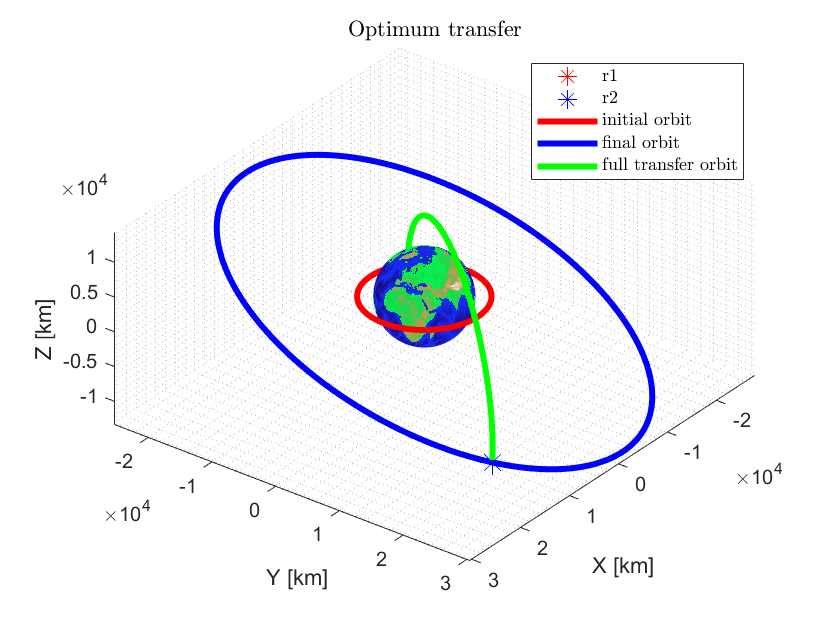

% get coe to plot orbits
optimum.state.r = optimum.r2;
optimum.state.v = optimum.v2;
[optimum.coe] = rv2coe(muE, optimum.state);

% get ellipse coordinates for initial and final orbits plot
optimum.r1_coords = ellipse_coords(muE, optimum.a1, optimum.e1, ....
                                   optimum.Omega1, optimum.inc1, optimum.omega1);
optimum.r2_coords = ellipse_coords(muE, optimum.a2, optimum.e2, ...
                                   optimum.Omega2, optimum.inc2, optimum.omega2);
optimum.rt_coords = ellipse_coords(muE, optimum.coe.a, norm(optimum.coe.e), ...
                                   optimum.coe.Omega, optimum.coe.inc, optimum.coe.omega);

% optimum transfer
figure(2)
earth_sphere('km');
hold on
plot3(optimum.r1(1), optimum.r1(2), optimum.r1(3), 'r*', ...
      optimum.r2(1), optimum.r2(2), optimum.r2(3), 'b*', 'MarkerSize',12)
hold on 
plot3(optimum.r1_coords(1,:), optimum.r1_coords(2,:), optimum.r1_coords(3,:), 'r', ...
      optimum.r2_coords(1,:), optimum.r2_coords(2,:), optimum.r2_coords(3,:), 'b', ...
      optimum.rt_coords(1,1:end/2), optimum.rt_coords(2,1:end/2),  ...
      optimum.rt_coords(3,1:end/2), 'g', 'LineWidth',3)
title('Optimum transfer','interpreter','latex')
hold off
grid minor
legend('r1','r2','initial orbit','final orbit',' full transfer orbit',...
    'location','northeast','interpreter','latex')
axis equal

## Discussion

The optimization analysis was initially performed by evaluating the cost function in a 3D mesh grid of 20x20x20 points, so a total of 8000 possible Lambert trajectories was evaluated. A larger number of evaluation points could have been chosen but the computational cost would have increased by a cubic power. The exploration minimum cost in the grid was found to be 3.462 km/s for the values θ1 =  208.421 deg, θ2 = 151.579 deg and tf = 16330.172 s. Therefore, this point was used as an initial guess for the Matlab built-in optimizer **fminsearch. **One could have thought of avoiding the initial exploration and going directly to the Matlab optimizer but the initial analysis allows to reduced the space of the design exploration running several cases of the **cost **function, which is less complex than the optimizer tool and allows to set an initial guess for the optimizer. The final minimum point was found to be a deltaV of 3.388 km/s for the corresponding variables θ1 = 232.626 deg, θ2 = 168.697 deg and tf = 14987.226 s. This transfer orbit can be seen in the above figure, which was computed by running the Lambert problem for the design variables value. From the isosurface region plots, one can observe that the lower energy solutions can be found in very concrete areas of the grid. Concretely in two, one corresponding to θ1 1st  quadrant values and θ2 4th quadrant, and the other one, θ1 between the 2nd and 3rd quadrant values and θ2 2nd quadrant. Note that the optimum solution corresponds to this last area. For visualizing the problem step by step, a plotting tool called **ellipse_coords** was developed and it allows to obtain the coordinates of the full orbit ellipse.